% 0. Read Data

% Read abdomenal signals
[sig1, ~, ~] = rdsamp('/mcode/databases/a03', 1);

[sig2, ~, ~] = rdsamp('/mcode/databases/a03', 2);
[sig3, ~, ~] = rdsamp('/mcode/databases/a03', 3);
[sig4, fs, time] = rdsamp('/mcode/databases/a03', 4);

% Read annotated fetal QRS locations
fileID = fopen('setAfqrs\a03.fqrs.txt','r');
directImpulse = fscanf(fileID,'%d');
fclose(fileID);

X_raw = [sig1 sig2 sig3 sig4];
[ndt, ns]=size(X_raw);
machka=5;

% Plot of raw signals
%{
subplot(4,1,1);
plot(sig1)
title('raw 1')
    
subplot(4,1,2); 
plot(sig2)
title('raw 2')  

subplot(4,1,3); 
plot(sig3)
title('raw 3')
   
subplot(4,1,4); 
plot(sig4)
title('raw 4')
%}

% FFT of raw data
%{
y = fft(sig3);
n = length(sig3);       % number of samples
f = (0:n-1)*(fs/n);     % frequency range
power = abs(y).^2/n;    % power of the DFT
plot(f,power);
xlabel('Frequency');
ylabel('Power');
%}

% 1. Preprocessing

% Detrending
n=10;
%{
D1 = detrend(X_raw(:,1),n); % removes the nth degree polynomial trend
D2 = detrend(X_raw(:,2),n);
D3 = detrend(X_raw(:,3),n);
D4 = detrend(X_raw(:,4),n);
%}
%X_d = [D1 D2 D3 D4];
X_d = X_raw;

% Bandpass filtering
order = 2530;
[X_bp, delay_bp] = bandpassFilter(X_d,BandPassCutoff3Hz,order,0); 
% delay is not used throughout since signal is centred

% Notch filtering
X_nf = FecgNotchFilt(X_bp,fs);

% FFT of raw data
%{
y = fft(X_nf(:,3));
n = length(X_nf(:,3));  % number of samples
f = (0:n-1)*(fs/n);     % frequency range
power = abs(y).^2/n;    % power of the DFT
plot(f,power);
xlabel('Frequency');
ylabel('Power');
%}

% Impulse artefact cancellation
X_im=FecgImpArtCanc(X_nf,fs,'',0);

% ICA to preprocessed signals
Z = [X_im(:,1), X_im(:,2), X_im(:,3), X_im(:,4)];
Z = transpose(Z);
r = 4;
[Zica, W, T, mu] = fastICA(Z,r);

***** Fast ICA (kurtosis) *****
Iter 001: max(1 - |<w001, w000>|) = 0.5794
Iter 002: max(1 - |<w002, w001>|) = 0.02006
Iter 003: max(1 - |<w003, w002>|) = 0.03526
Iter 004: max(1 - |<w004, w003>|) = 0.03851
Iter 005: max(1 - |<w005, w004>|) = 0.004259
Iter 006: max(1 - |<w006, w005>|) = 0.000312
Iter 007: max(1 - |<w007, w006>|) = 8.156e-05
Iter 008: max(1 - |<w008, w007>|) = 2.301e-05
Iter 009: max(1 - |<w009, w008>|) = 6.503e-06
Iter 010: max(1 - |<w010, w009>|) = 1.837e-06
Iter 011: max(1 - |<w011, w010>|) = 5.191e-07



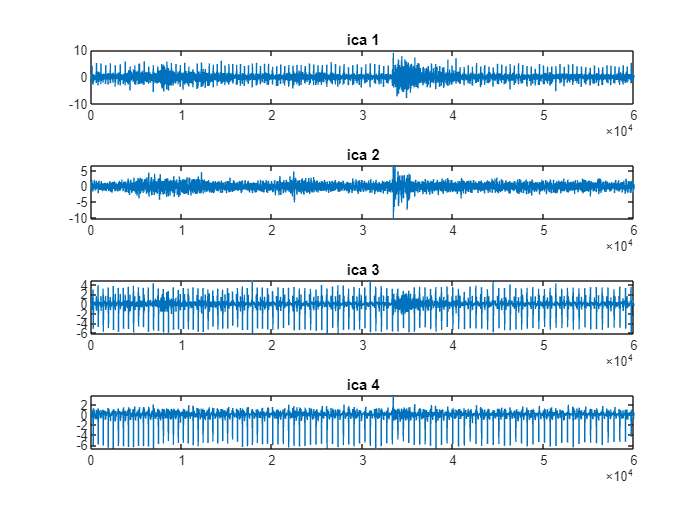


ica1 = Zica(1,:);
ica2 = Zica(2,:);
ica3 = Zica(3,:);
ica4 = Zica(4,:);

subplot(4,1,1);
plot(ica1)
title('ica 1')

subplot(4,1,2);
plot(ica2)
title('ica 2')

subplot(4,1,3);
plot(ica3)
title('ica 3')

subplot(4,1,4);
plot(ica4)
title('ica 4')

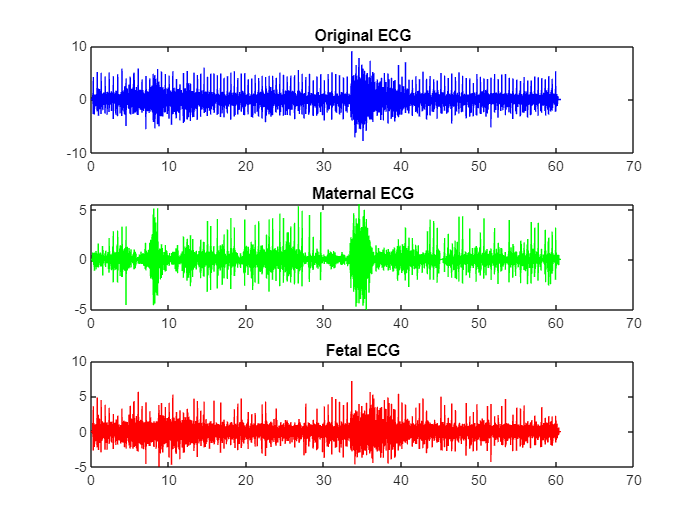

% 2. mECG cancellation

templateSize = 20;
windowTime = 0.063;
[fecg1, mecg1, ~] = cancelMecg(ica1, fs, templateSize,0,1);

[fecg2, mecg2, ~] = cancelMecg(ica2, fs, templateSize,0,0);
[fecg3, mecg3, ~] = cancelMecg(ica3, fs, templateSize,0,0);
[fecg4, mecg4, delayValue] = cancelMecg(ica4, fs, templateSize,0,0);

[f1, estimatedR] = compareDirect(fecg1, directImpulse, delayValue, fs)

f1 = 0.3150

estimatedR =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


[f1, estimatedR] = compareDirect(fecg2, directImpulse, delayValue, fs)

f1 = 0.2976

estimatedR =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


[f1, estimatedR] = compareDirect(fecg3, directImpulse, delayValue, fs)

f1 = 0.8185

estimatedR =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


[f1, estimatedR] = compareDirect(fecg4, directImpulse, delayValue, fs)

f1 = 0.6717

estimatedR =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


% 3. ICA/Post-processing

% Try ICA for separating noise and signals of interest
Z = [fecg1, fecg2, fecg3, fecg4];
Z = transpose(Z);
r = 4;
[Zica, W, T, mu] = fastICA(Z,r);

***** Fast ICA (kurtosis) *****
Iter 001: max(1 - |<w001, w000>|) = 0.5242
Iter 002: max(1 - |<w002, w001>|) = 0.008959
Iter 003: max(1 - |<w003, w002>|) = 0.009869
Iter 004: max(1 - |<w004, w003>|) = 0.01067
Iter 005: max(1 - |<w005, w004>|) = 0.01016
Iter 006: max(1 - |<w006, w005>|) = 0.00843
Iter 007: max(1 - |<w007, w006>|) = 0.006465
Iter 008: max(1 - |<w008, w007>|) = 0.007605
Iter 009: max(1 - |<w009, w008>|) = 0.00968
Iter 010: max(1 - |<w010, w009>|) = 0.006819
Iter 011: max(1 - |<w011, w010>|) = 0.002122
Iter 012: max(1 - |<w012, w011>|) = 0.0004073
Iter 013: max(1 - |<w013, w012>|) = 6.946e-05
Iter 014: max(1 - |<w014, w013>|) = 1.212e-05
Iter 015: max(1 - |<w015, w014>|) = 2.222e-06
Iter 016: max(1 - |<w016, w015>|) = 4.361e-07




ica1 = Zica(1,:);
ica2 = Zica(2,:);
ica3 = Zica(3,:);
ica4 = Zica(4,:);


% 4. F1 calculation
comparedSignal = ica1;
[f1, estimatedR] = compareDirect(comparedSignal, directImpulse, delayValue, fs);
f1=f1

f1 = 0.8750

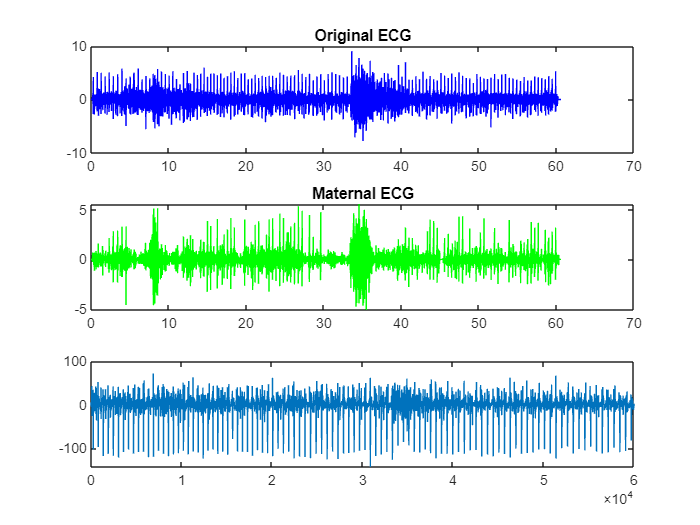

% RLS adaptive filter
d = X_im(:,1);
x = transpose(mecg1(201:length(mecg1)-401));
taps = 5;
fFactor = 1;
rls= dsp.RLSFilter(taps,"ForgettingFactor",fFactor);
[y,e] = rls(x,d);
w = rls.Coefficients;
plot(e);

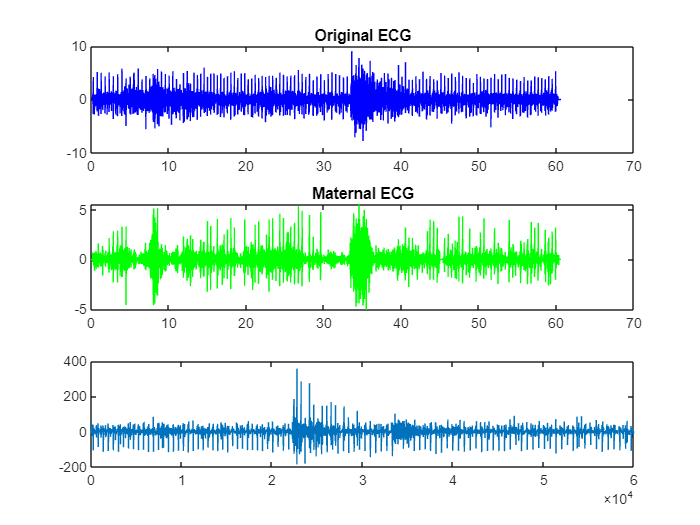

% Try an adaptive LMS filter

l=30; 
mu=0.01;
lms = dsp.LMSFilter('Length',l,'StepSize',mu,'Method','Normalized LMS');
mecg1 = transpose(mecg1);
[y,e,w] = lms(mecg1(delayValue:length(X_im(:,1))+delayValue-1),X_im(:,1));
plot(y)
plot(e)

% Adaptive Filter
%{
d = X_im(:,1);
x = transpose(mecg1(201:length(mecg1)-301));
lms = dsp.LMSFilter;
[y,err,wts] = lms(x,d);
plot(err)
%}


%Wavelet Fun
%{
[swa1,swd1] = swt(fecg1(201:(length(fecg1)-269)),7,'db1');
[swa2,swd2] = swt(fecg2(201:(length(fecg2)-269)),7,'db1');
[swa3,swd3] = swt(fecg3(201:(length(fecg3)-269)),7,'db1');
[swa4,swd4] = swt(fecg4(201:(length(fecg4)-269)),7,'db1');
sLen = 60000;
swd11 = transpose(swd1(5,:));
swa11 = transpose(swa1(5,:));
swd22 = transpose(swd2(5,:));
swa22 = transpose(swa2(5,:));
swd33 = transpose(swd3(5,:));
swa33 = transpose(swa3(5,:));
swd44 = transpose(swd4(5,:));
swa44 = transpose(swa4(5,:));

%subplot(2,1,1)

plot(swa11)
xlim([0 sLen])
title('Level 7 Approximation coefficients')
subplot(2,1,2)
plot(swd11)
xlim([0 sLen])
title('Level 7 Detail coefficients')

Z = [swa11, swa22, swa33, swa44];
Z = transpose(Z);
r = 4;
[Zica, W, T, mu] = fastICA(Z,r);

ica1 = Zica(1,:);
ica2 = Zica(2,:);
ica3 = Zica(3,:);
ica4 = Zica(4,:);

comparedSignal = swa33;
[f1, estimatedR] = compareDirect(comparedSignal, directImpulse, 0, fs);
f1=f1
%}

% Plot

% Plot ica results
%{
subplot(4,1,1);
plot(ica1)
title('ica 1')

subplot(4,1,2);
plot(ica2)
title('ica 2')

subplot(4,1,3);
plot(ica3)
title('ica 3')

subplot(4,1,4);
plot(ica4)
title('ica 4')

%}
% mECG plots
%{
subplot(4,1,1);
plot(mecg1)
title('mECG 1')
    
subplot(4,1,2); 
plot(mecg2)
title('mECG 2')  

subplot(4,1,3); 
plot(mecg3)
title('mECG 3')
   
subplot(4,1,4); 
plot(mecg4)
title('mECG 4')
%}

% fECG plots
%{
subplot(4,1,1);
plot(fecg1)
title('fECG 1')
    
subplot(4,1,2); 
plot(fecg2)
title('fECG 2')  

subplot(4,1,3); 
plot(fecg3)
title('fECG 3')
   
subplot(4,1,4); 
plot(fecg4)
title('fECG 4')
%}

%{
subplot(4,1,1);
plot(X_im(:,1))
title('Imp 1')
    
subplot(4,1,2); 
plot(X_im(:,2))
title('Imp 2')  

subplot(4,1,3); 
plot(X_im(:,3))
title('Imp 3')
   
subplot(4,1,4); 
plot(X_im(:,4))
title('Imp 4')
%}

